# Diagram of signal processing  

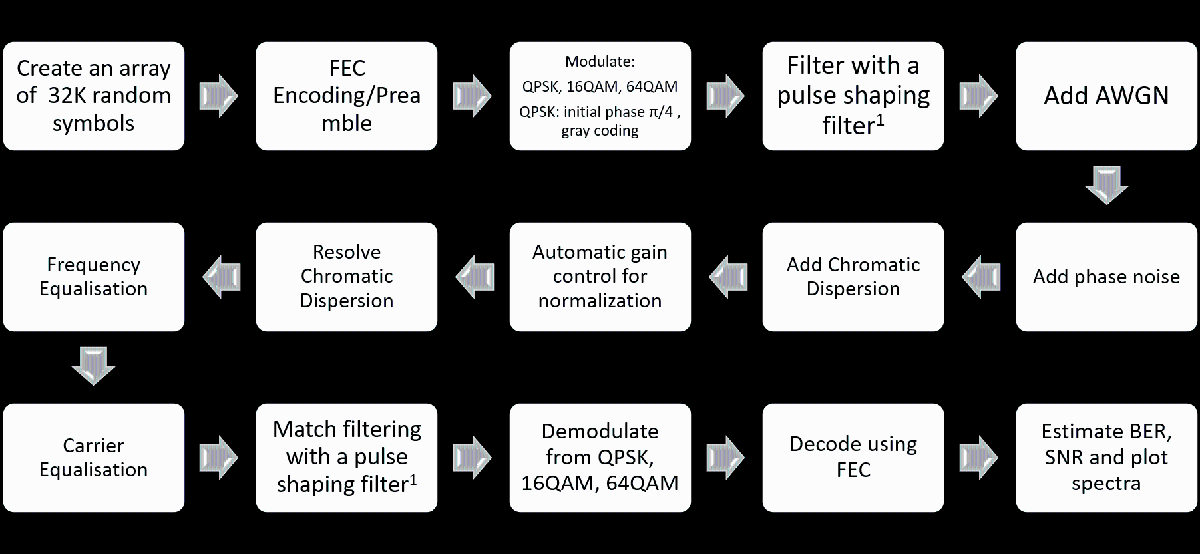

## Constants and Initial Conditions

%Resetting the rng seed
rng("default");
rng(1960);

enable_FEC = false;
enable_pulse_shaping= false;
enable_AWGN = false;
enable_phase_noise = false;
enable_chromatic_dispersion = false;
enable_AGC = false;
enable_frequency_equal = false;
enable_carrier_equal = false;


num_symbols = 32*1024; 
symbol_rate = 100e9;
time_step = 1/symbol_rate;
linewidth = 100e3;
variance = 2*pi*linewidth*time_step;

## Modulation

%BPSK
M = 2;
symbols = randi([0 M-1],1,num_symbols);
bpsk_mod = pskmod(symbols,M,0,'gray');


%QPSK
M = 4;
symbols = randi([0 M-1],1,num_symbols);
qpsk_mod = pskmod(symbols,M,pi/M,'gray');


%16QAM
M = 16;
symbols = randi([0 M-1],1,num_symbols);
qam16_mod = pskmod(symbols,M,pi/M,'gray');


%64QAM
M=64;
symbols = randi([0 M-1],1,num_symbols);
qam64_mod = pskmod(symbols,M,pi/M,'gray');

%{
figure
subplot(2,2,1,gca);
plot(bpsk_mod,'*','MarkerEdgeColor','blue','MarkerFaceColor',"blue");
title("BPSK Modulated symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
xlim([-1,1]);
ylim([-1,1]);
grid on;
subplot(2,2,2);
grid on;
plot(qpsk_mod,'*','MarkerEdgeColor','black','MarkerFaceColor',"black");
title("QPSK Modulated symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
grid on;
subplot(2,2,3);
plot(qam16_mod,'*','MarkerEdgeColor','red','MarkerFaceColor',"red");
title("16 QAM Modulated symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
grid on;
subplot(2,2,4);
plot(qam64_mod,'*','MarkerEdgeColor','green','MarkerFaceColor',"green");
title("64 QAM Modulated symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
title("Modulated Symbols");
grid on;
%}

## Demodulation